# Task 2: Data processing

## Task description

Within this task, the data of a NIR sensor should be analysed. The composition needs to be calculated and a useful demonstrative picture should be generated. Furthermore, the results should be compared to the results generated by a software provided by the company Siemens. 

## Calculation of the composition

The CSV file contains a lot of numbers. Each number represents a material as seen in the picture below. To calculate the percentages for each material, the amount of each number needs to be devided by the total amount of pixels.

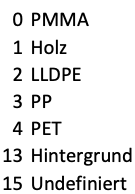 

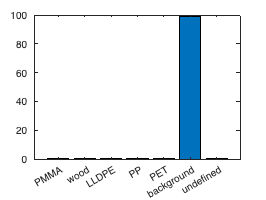

load('exportnir.csv');

% I deleted the first column as it is a (for this
% excercise) useless timestamp

if width(exportnir) == 313
    exportnir(:,1) = [];

end

% total amount of pixels and of each material class

total = size(exportnir, 1) * size(exportnir, 2);



% creating a table with material id and respective material class
material_id = [0;1;2;3;4;13;15];
material_class = {'PMMA';'wood';'LLDPE';'PP';'PET';'background';'undefined'};
material_colour = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 1, 1, 1; 0.3010, 0.7450, 0.9330];

material_table = table(material_id, material_class, material_colour);




% calculating the composition with a loop
for i = 1:length(material_id)

    material_sum = sum(exportnirWalch(:) == material_id(i));
    material_comp = (material_sum/total)*100;
    material_table.abs_comp(i) = material_sum;
    material_table.composition(i) = material_comp;

end

x = material_table.material_class;
y = material_table.composition;

bar(x,y)

### Explanation

Within the first steps of this code, the total amount of pixels is calculated and a table with the necessary information about the material classes and their respective IDs is created. With a for loop, the code iterates through the material_table and takes each material_id to compare it to the entire exportnir. This creates the sum of all the pixels that refer to each material. With this, the composition can be calculated. Both the absolute amount of pixels and the percentages are added to the table.

### Interpretation

Below are screenshots of the results of this code and the results from the software that is provided by Siemens. Interesting about the Siemens data is that 99.25% are supposed to be PP and the rest of the materials are somewhere below 0.28%. This is rather unrealistic as the material class with the highest percentage is expected to be the background. This is true for the data analysed with this code. The background makes up to 99.16% of all material classes. However, some material classes have the same or very similar (±1) composition persentages in both calculations (PMMA, wood, PET, LLDPE, undefined). This implys that the main problem with the siemens calculation is about proper classification of PP and the background as these two classes show the biggest differences in both calculations.

#### Results of this code

### 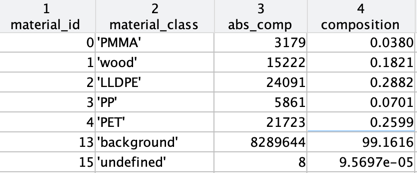

#### Results of Siemens

### 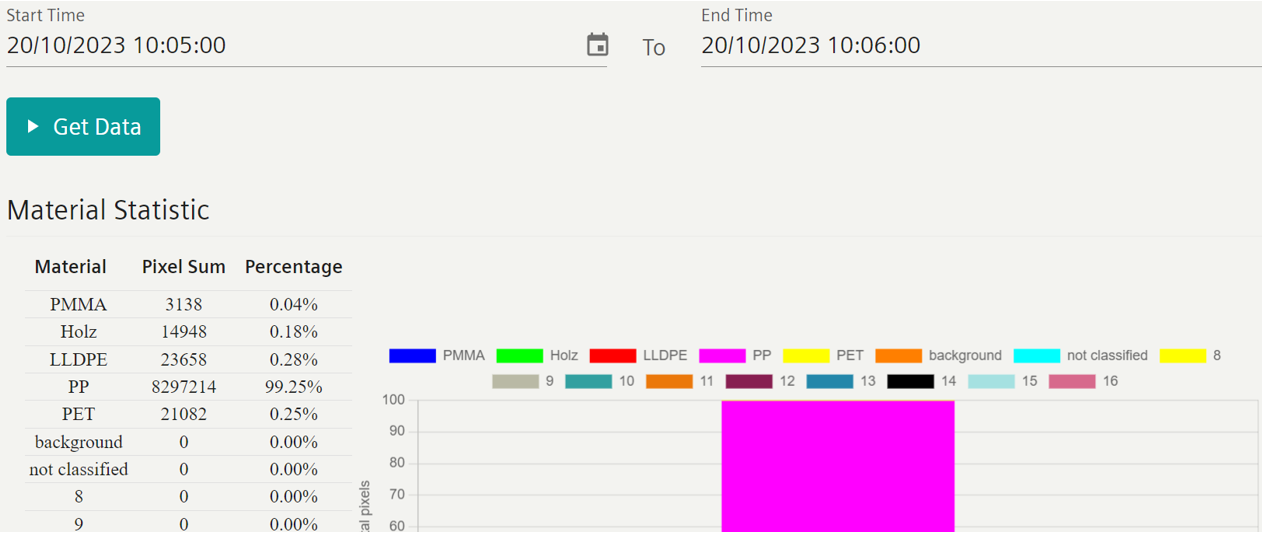

## Plotting the image

First, an area of the data is selected that shows different material classes. This area is then transformed into an image that displays the different material classes with different colours.

### Finding the most interesting area

% define a range that i later want to look at. the range should contain an
% interesting area of the image. how do i get an interesting area? since
% background and undefined are the highest numbers the most interesting
% areas should have the lowest total sum within my range. so i need to find
% the area with the lowest sum (of the material id)

roi_height = 500;

best_roi = [];
best_score = realmax; % biggest number in matlab


for i = 1:(size(exportnir, 1) - roi_height + 1)

    current_region = exportnir(i:(i + roi_height - 1), :);
    sum_current_region = sum(current_region, 'all');

    
    if sum_current_region < best_score

        best_score = sum_current_region;
        best_roi = current_region;
    end
end

### Plotting

for i = 1:height(material_table)

    position = height(material_table) - i + 1; % getting at the bottom of things
    
    best_roi(best_roi==material_id(position)) = position; % reassigning the material_ids in the matrix

end

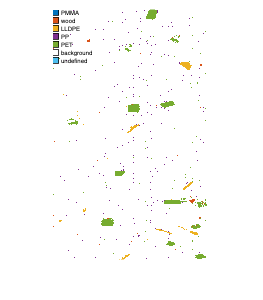

num_colours = numel(material_id);
roi_image = ind2rgb(best_roi, my_map);

imshow(roi_image);

hold on;
draw_legend(material_table);
hold off;

### Explanation

In order to plot an image from the given matrix, a loop was created to find the most interesting part of the matrix. The most interesting part of the matrix has the lowest sum of all the values within the box that is chosen to be the size of the image. This is the case because the background and undefined materials have the highest numbers (13 and 15). This means that the most interesting part of the matrix has the lowest sum as the intersting parts (the materials) have lower numbers than the background. With an if statement, the most interesting region gets asigned to the variable best_roi.

For the plotting, a function was created that adds a legend. However, the function ind2rgb did not properly work with creating a legend as well because the colours of the legend and the colours of the image were misalligned. This was the case because the material_ids were no a continuous array starting with 1 (1,2,3, ...). The array had a jump from 4 to 13. This created the wrong assignment of colours and legend. In order to fix this issue, the material_id s had to be reassigned to fill a proper array starting with 1 and ending with the height of the table. Therefore, a loop was created that looped through the highest number first.

## Functions

function draw_legend(table)
    legend_height = 16;

    for i = 1:height(table)

        text(16, 6 + (i-1)* legend_height, table.material_class(i), 'FontSize', 6);
        rectangle('Position', [0 ((i-1) * legend_height) 12 12], 'FaceColor', [table.material_colour(i, 1) table.material_colour(i, 2) table.material_colour(i, 3)]);

    end

end

### Explanation

This function draws a text with the material_class and a rectangle with the colour of the material_class. The loop makes sure that every text and rectangle is moved a bit down so the texts would not overlap.